# Figure 4: Ring model is a nice approximation of sparse network model ( $s$ = 0.1 through all the section)

### FIgure A: Visualize the firing rate with different initial condition

We first generate steady weight matrix using weight simulation. Once we had it, we run firing rate simulation for 1 second with time step equals to 0.5 miliseconds to illustrate the evolution of firing rate with different initial condition.

Since the network is sparse,  there are $N\cdot M \cdot s$ active neurons at each environment. So, for initial condition at environment $n$, it means that the active neurons at that environment are considered in the firing rate simulation and the rest is ignored. Also, for those active cells, we provided a bump initial condition (depending $r_0$) according to theirs phase. The value of  $r_0$  depends on the branch they have, since we considerar quadratic response function. 

The generation of weight matrix and firing rate simulation can be found in section **Figure 4** and **Figure 4A** with proper parameters in script ***9_generate_network_weight.mlx.***

Here, we use the firing rate at steady state and filter it by active cells, then compute the mean across each postion, later represent them in a heatmap. Same for the rest environment. 

Export figure setup:2.4    / 2

clear; clc;
load(fullfile(read_output_dir(), "Fig4\FR_illustration.mat"))

method = "mean";

etas = [eta_1, eta_2, eta_3];

fig_size = 120;
for eta = etas
    figure
    FR_plot(Env_track, phase, d_t, FR_tracker_eta0, eta, method)
    fig_config(fig_size)
end

for eta = etas
    figure
    FR_plot(Env_track, phase, d_t, FR_tracker_eta1, eta, method)
    fig_config(fig_size)
end

for eta = etas
    figure
    FR_plot(Env_track, phase, d_t, FR_tracker_eta10, eta, method)
    fig_config(fig_size)
end


% get the colobar to make the additional information, only give intuitive
% idea
c = colorbar;
c.Limits = [0, 13]
c.Ticks = [0, 12]
c.FontSize = 30

### Fig C: Amplitude of the bump vs $w_1$ for $w_0$ < 0 

For I0 = 0.2, w0 = -0.25, and w_max = 40, we ran simulations for the network model with different $\eta$, from 0 to whatever value that makes the $w_1$ small, and the ring model to make a comparison of bifurcation diagram. For each $w_1$, we run two simulation for each model, one with large bump initial condition and one with small bump initial condition to check whether the constant firing rate 0 is attractor.  The y-axis indicates the bump amplitude computed as twice of first fourier mode of the mean Firing rate (average between the group) and x-axis represents the lag. 

Export figure setup: 6 - 4

Inkscape 89.250 - 59.500

    4.1111



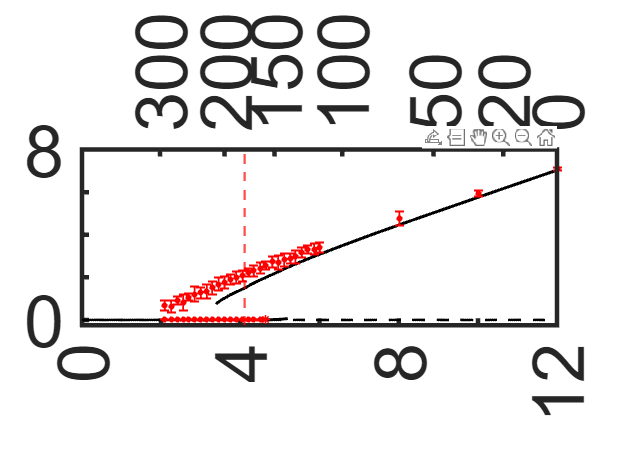

clear; clc;
s = 0.1;
fig_size = 40;
inner_plot = false;
top_axis = true;

ring_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot1_Ring.mat");
net_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot1.mat");

Amplitude_diagram(s, ring_file, net_file, fig_size, inner_plot, top_axis)

### Fig D: display the bump amplitude of certain initial condition ($\eta$) over quasi-all environment

We first run firing rate simulation of a weight matrix at environment $\eta$ to obtain the population firing rates. Then,  we project the population firing rates to each of past explored environments to obtain the bump amplitude. At the end, we average the bump amplitude at each environment cross all the weight matrix.

Export figure setup: 4.5 - 3

    "eta = 30, w1 = 10.0178"



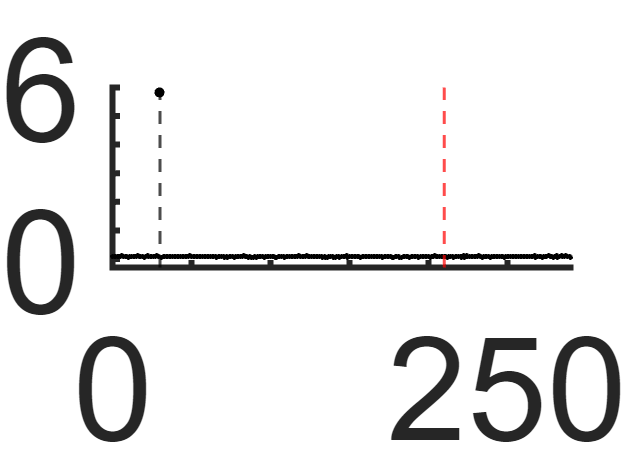

    "eta = 115, w1 = 6.0064"



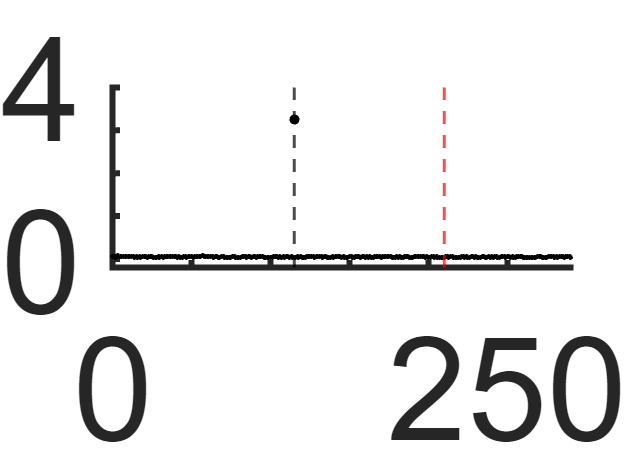

    "eta = 147, w1 = 4.9543"



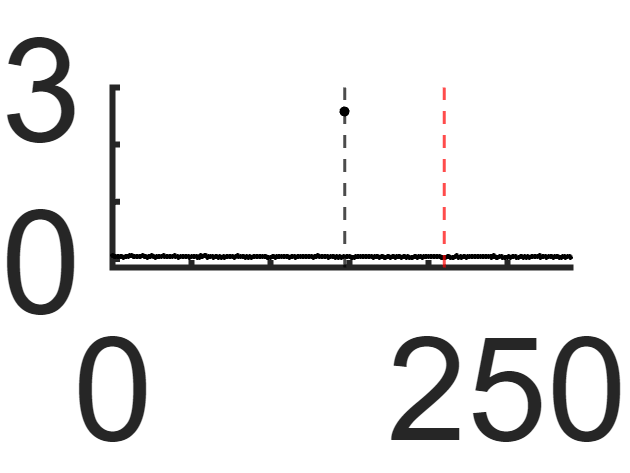

    "eta = 222, w1 = 3.1547"



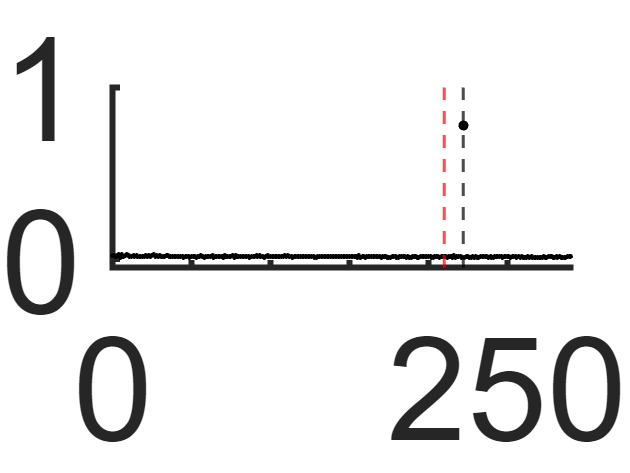

clear; clc;
s = 0.1;
fig_size = 80;

ring_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot1_Ring.mat");
load(ring_file, "amplitude_T", "etas_seq")

pos = find(amplitude_T(1, :) >= 0.5, 1,  "last");
eta_cap = etas_seq(1, pos);

display_bump_amp_env(s, eta_cap, fig_size)

### Fig E: display the bump profile for some initial condition and some weight matrix

No need extrac code to generate inputs.

4.5 - 3

clear; clc; 
P = 0.3; D = 0.3; s = 0.1; seed = 1987; eta = 30;
visualized_etas = [0, eta-1, eta, eta+1];

fig_size = 80;
display_cross_bump_profile(P, D, s, seed, eta, visualized_etas, fig_size)

### Fig F: generate the phase plane for the Turing bifurcation

Using linear stability analysis of the ring model, we obtain the analytical expression of the Turing bifurcation, solid black line. Also, we can run simulation of ring model without noise to obtain the saddle node bifurcation, dashed line.  Finaly, we add dots from the network model ( $w_1$ computed using the analytical expression of the amplitude scaled with $w_{max}$).

The computation of the saddle node bifucartion can be found in the section **Figure 4F** with proper parameters in script ***9_generate_network_weight.mlx.***

Export figure setup:6-4

Ink: 80-60

clear; clc;

% generate the dots.
file_name = fullfile(read_output_dir(), "Fig4\phase_diagram.mat");

display_phase_diagram(file_name)

## Auxiliar functions

function FR_plot(Env_track, phase, d_t, FR_tracker, eta, method)
    ind_evn = Env_track(:, end - eta);
    
    FR_tracker_Env = FR_tracker(ind_evn, :);
    
    total_time_ms =size(FR_tracker_Env, 2);
    times_sec = ((1:total_time_ms)-1) * d_t / 1000; % to s
    
    mean_FR_tracker = grpstats(FR_tracker_Env, phase, {method});
    max(max(mean_FR_tracker));
    imagesc(times_sec, unique(phase), mean_FR_tracker)
    xlim([0, 1])
    xticks([0, 1])
   % xlabel("times (s)")
    yticks([-pi, 0, pi])
    yticklabels(["-\pi", 0, "\pi"])
    %box off
end

function Amplitude_diagram(s, ring_file, net_file, fig_size, inner_plot, top_axis)
    
    if nargin < 4
        fig_size = 80;
        inner_plot = false;
        top_axis = false;
    end
    
    if nargin < 5
        inner_plot = false;
        top_axis = false;
    end
    
    load(ring_file)
    
    figure
    t = tiledlayout(1,1);
    ax1 = axes(t);
    plot(ax1, w1s, mean_flat, "k-", "LineWidth", 2)
    hold on
    plot(ax1, w1s, mean_bump, "k-", "LineWidth", 2)

    
    [w1_crit, w1_ring] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    disp(w1_crit)
    % extend stable line
    w1_stable = 0:0.01:(min(w1s)+0.01);
    stable_part = zeros(1, length(w1_stable));
    w1_unstable = w1_crit:0.01:max(w1s);
    unstable_part = zeros(1, length(w1_unstable));
    
    plot(ax1, w1_stable, stable_part,  "k-", "LineWidth", 2);
    plot(ax1, w1_unstable, unstable_part, "k--", "LineWidth", 2)
    
    
    % load network
    load(net_file)
    flat_ind = var_flat == 0;
    w1s_flat_strange = w1s(flat_ind);
    mean_flat_strange = mean_flat(flat_ind);
    mean_flat(flat_ind) = nan;
    var_flat(flat_ind) = nan;
    
    bump_ind = var_bump == 0;
    w1s_bump_strange = w1s(bump_ind);
    mean_bump_strange = mean_bump(bump_ind);
    mean_bump(bump_ind) = nan;
    var_bump(bump_ind) = nan;
    
    errorbar(ax1, w1s, mean_bump, 1.96*sqrt(var_bump), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
    errorbar(ax1, w1s, mean_flat, 1.96*sqrt(var_flat), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
    if sum(flat_ind) > 0 
        plot(ax1, w1s_flat_strange, mean_flat_strange, "r*", "LineWidth", 1)
    end
    if sum(bump_ind) > 0
        plot(ax1, w1s_bump_strange, mean_bump_strange, "r*", "LineWidth", 1)
    end
    
    hold off
    xline(w1_crit, "r--", "LineWidth", 1.5)
    xlim([0, 12])
    xticks(0:2:12)
    xticklabels([0,  "", 4, "", 8, "", 12])
    
    ylim([-0.25, 8])
    yticks([0, 2, 4, 6, 8])
    yticklabels([0, "", "", "", 8])
    fig_config(fig_size)
    set(gca, 'LineWidth', 3)
    
    if inner_plot
        axes('Position',[.6 .2 .27 .20])
        plot(w1_backward(amp_backward <= 0.5), amp_backward(amp_backward <= 0.5), "k-", "LineWidth", 2)
        hold on
        plot(w1_backward(amp_backward > 0.5), amp_backward(amp_backward > 0.5), "k-", "LineWidth", 2)
        plot(w1_forward(amp_forward <= 0.5), amp_forward(amp_forward <= 0.5), "k-", "LineWidth", 2)
        plot(w1_forward(amp_forward > 0.5), amp_forward(amp_forward > 0.5), "k-", "LineWidth", 2)
        errorbar(w1s_network, mean_bump, 1.96*sqrt(var_bump), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
        errorbar(w1s_network, mean_flat, 1.96*sqrt(var_flat), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
        xline(w1_crit, "--k", "LineWidth", 2)
        hold off
        box off
        xlim([2, 6])
        xticks(2:2:6)
        xticklabels([2, "",  6])
        ylim([-0.5, 4])
        yticks([0, 2, 4, 6])
        yticklabels([0, "", 4])
        set(gca, 'fontsize', fig_size/1.5)
        set(gca, 'LineWidth', 3)
    end
    
    if top_axis
        etas_axis = flip([0, 20, 50, 100, 150, 200, 300]);
        f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;
        w1s_axis = w_max * f(P, D, etas_axis, s);
        
        ax2 = axes(t);
        ax2.XAxisLocation = 'top';
        ax2.YAxisLocation = 'right';
        %ax2.YAxis.Visible = 'off';
        ax2.XLim = [0, max(w1s_axis)];
        ax2.XTick = [0, w1s_axis];
        ax2.XTickLabel = ["", etas_axis];
        ax2.Color = 'none';
        ax1.Box = "off";
        %ax2.Box = 'off';
        set(gca, 'fontsize', fig_size*1.2)
        set(gca, 'LineWidth', 3)
        set(gca,'ytick',[])
    end
end


function [w1_crit, w1_crit_ring] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track)
    r0 = (1 - 2*w0*I0 - sqrt(1 - 4*w0*I0)) ./ (2*w0.^2);
    w1_crit_ring = 1 ./(w0*r0+I0);
    
    is_stack = true;
    eta = 0;
    w1_aux = 999;
    while w1_aux > w1_crit_ring
        [~, ~, ~, amp, A, ~, C] = Compute_mean_variance(P, D, eta, is_stack, M, s, nan, w0, w_max);
        w1_aux = amp + sqrt(A + C/2) * sqrt(2*pi/(n_ca3_per_track));
        
        eta = eta + 0.1;
    end

    f = @(P, D, eta, s) 2*P*D./(P+D)*(1-s^2*(P+D)).^eta;
    w1_crit = w_max * f(P, D, eta, s);
end


function display_bump_amp_env(s, eta_cap, fig_size)
    file_dir = read_output_dir();
    load_file = "Fig4\Amp_cross_s=" + strrep(string(s), ".", "dot") + ".mat";
    
    load(fullfile(file_dir, load_file));
    
    for i = 1:length(desired_w1s)
        mean_i = mean_bump_amp{i};
        var_i = var_bump_amp{i};
        
        eta = which_eta(i);
        w1 = which_w1(i);
        
        y_max = ceil(max(mean_i));
        
        display("eta = " + eta + ", w1 = " + w1)
        figure
        plot(etas, mean_i, "k.", "MarkerSize", 10)
        hold on
        plot(eta, mean_i(etas == eta), "k.", MarkerSize = 20)
        hold off
        xline(eta, "k--",  "LineWidth", 2)
        xline(eta_cap, "r--", "LineWidth", 2)
        box off
        axis tight
        fig_config(fig_size)
        xticks(0:50:250)
        xticklabels([0, "", "", "", "", 250])
        ylim([-y_max*0.05, y_max])
        yticks(0:y_max)
        yticklabels([0, repelem("", 1, y_max -1), y_max])
    end
end

function list_files = look_files_by_pattern(dir_name, patterns)    
    all_files = dir(dir_name);
    list_files = {all_files.name};
    for pattern = patterns
        list_files = list_files(contains(list_files, pattern));  
    end
end

function display_cross_bump_profile(P, D, s, seed, eta, visualized_etas, fig_size)
    file_dir = read_output_dir() + "\P=" + strrep(string(P), ".", "dot") + ...
            "D=" + strrep(string(D), ".", "dot");
    
    file = look_files_by_pattern(file_dir, ["FR", "s=" + strrep(string(s), ".", "dot"), string(seed)]);
    load(fullfile(file_dir, file))
    
    indice = etas_seq(1, :) == eta;
    FR_complete = FR_total{1};
    FR_complete = FR_complete(indice, :);
    
    for eta_i = visualized_etas
        Env_ind = Env_track(:, end - eta_i);
        FR_Env = FR_complete(Env_ind);
        FR_mean = grpstats(FR_Env, phase, "mean");
        
        ymax = ceil([max(FR_Env)]);
        
        if not(mod(ymax, 2) == 0)
            ymax = ymax + 1;
        end
        
        figure
        plot(phase, FR_Env,  ".", "MarkerSize", 15)
        hold on
        plot(unique(phase), FR_mean, "k-", "LineWidth", 2)
        hold off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels(["-\pi", "", "\pi"])
        ylim([-ymax*0.05, ymax])
        yticks(0:2:ymax)
        yticklabels([0, repelem("", 1, ymax/2 -1), ymax])
        fig_config(fig_size)
        box off
    end
end

function display_phase_diagram(file_name)
    % generate the dots.
    load(file_name)
    
    max_eta = 240;
    etas = 0:20:max_eta;
    w0_default = -0.25; %%%%%%%%%%%%%
    etas2 = [0:10:max_eta];
    etas2 = etas2(not(ismember(etas2, etas)));
    etas3 = 210;
    w1_0 = w_max * f(P, D, etas, s);
    w0_0 = ones(length(w1_0), 1) * (w0_default);
    w1_1 = w_max * f(P, D, etas2, s);
    w0_1 = ones(length(w1_1), 1) * (w0_default);
    w1_2 = w_max * f(P, D, etas3, s);
    w0_2 = ones(length(w1_2), 1) * (w0_default);
    
    start_point = 6;
    end_point = 10;
    disp_width = 1;
    
    etas_20_w1 = w1_0; etas_20_w0 = w0_0;
    etas_10_w1 = w1_1; etas_10_w0 = w0_1;
    etas_crit_w1 = w1_2; etas_crit_w0 = w0_2;
    
    
    etas_20_w0(etas_20_w1 > start_point & etas_20_w1 < end_point) = [];
    etas_20_w1(etas_20_w1 > start_point & etas_20_w1 < end_point) = [];
    etas_20_w1(etas_20_w1 >= end_point) = etas_20_w1(etas_20_w1 >= end_point) - ...
        (end_point - start_point - disp_width);
    
    etas_10_w0(etas_10_w1 > start_point & etas_10_w1 < end_point) = [];
    etas_10_w1(etas_10_w1 > start_point & etas_10_w1 < end_point) = [];
    etas_10_w1(etas_10_w1 >= end_point) = etas_10_w1(etas_10_w1 >= end_point) - ...
        (end_point - start_point - disp_width);
    
    
    plot(etas_20_w1, etas_20_w0, "k.", "MarkerSize", 30)
    hold on
    plot(etas_10_w1, etas_10_w0, "k.", "MarkerSize", 15)
    plot(etas_crit_w1, etas_crit_w0, "r.", "MarkerSize", 25)
    plot(saddle_node_bif, w0_seq, "--k", "LineWidth", 2)
    plot(turing_bif, w0_seq, "-k", "LineWidth", 2)
    hold off
    
    box off
    ytick=get(gca,'YTick');
    text(start_point+disp_width/2,ytick(1),'//','fontsize',60);
    xticklabels(["", 2, "", 4, "", 6, 10, "", 12])
    ylim([-1, 0.75])
    yticks([-1:0.25:0.75])
    yticklabels([-1, "", -0.5, "", 0, "", 0.5, ""])
    set(gca, "LineWidth", 60/20)
    set(gca, "FontSize", 60)
    xlim([1, 9])
end
